clear; close;
ones([1, 2]);

time = 0 : 0.01 : 10;
x0 = [0;0;0];
x = zeros(length(time), 3);

Earth;
F = [0; 0; 0];
a = F./(m*w0*R0)

a =      0
     0
     0



r = sqrt((x(1) + 1)^2 + x(2)^2 + x(3)^2);
dx(1) = x(4);
dx(2) = x(5);
dx(3) = x(6);
dx(4) = 2*x(5) + (1 + x(1))*(1 - r^(-3)) + a(1);
dx(5) = -2*x(4) + x(2)*(1 - r^(-3)) + a(2);
dx(6) = -x(3)*r^(-3) + a(3);


tau = [1 6*pi]';

u = [[0;0] [0;0] [0;0]];
MDNS = 100;
size(u)

ans =      2     3


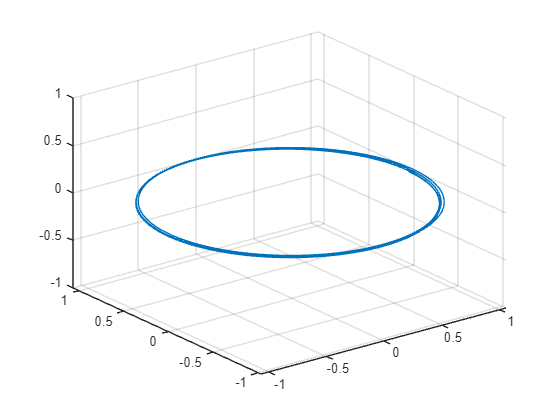

x0 = [0.01;0;0;0;0;0];


[t,x,~,~] = get_tx(tau,u,x0,MDNS);
%x_orb = X(:,1);
%y_orb = X(:,2);
%z_orb = X(:,3);
om=1;
xorb=zeros(length(t),3);
for k=1:length(t)
    c=cos(om*t(k));s=sin(om*t(k));
    R=[c -s 0;s c 0;0 0 1];
    xorb(k,:)=([x(k,1) x(k,2) x(k,3)]+[1 0 0])*R;
end


figure();
plot3(xorb(:,1), xorb(:,2), xorb(:,3));
grid on;